# Lab 5: Image Segmentation through K-Means

The goal of image segmentation is to partition an image into regions, each of which have a resonably homogenous visual appearance or which corresponds to similar objects or parts of an object. Each pixel in an image is a point in a 3-dimensional space comprising of the intensities of the red, blue, and green channels, and our segmentation algorithm simply treats each pixel in the image as a separate data point. We illustrate the result of running Kmeans, for any particular value of K, by re-drawing the image replacing each pixel vector with the (R,G,B} intensity triplet given by the centroid to with that pixel has been assigned. Results for various values of K based on example elephant.jpg are shown as follow. 

You have two images — elephant.jpg and eiffel.jpg, on which you will be running your K-Means code.

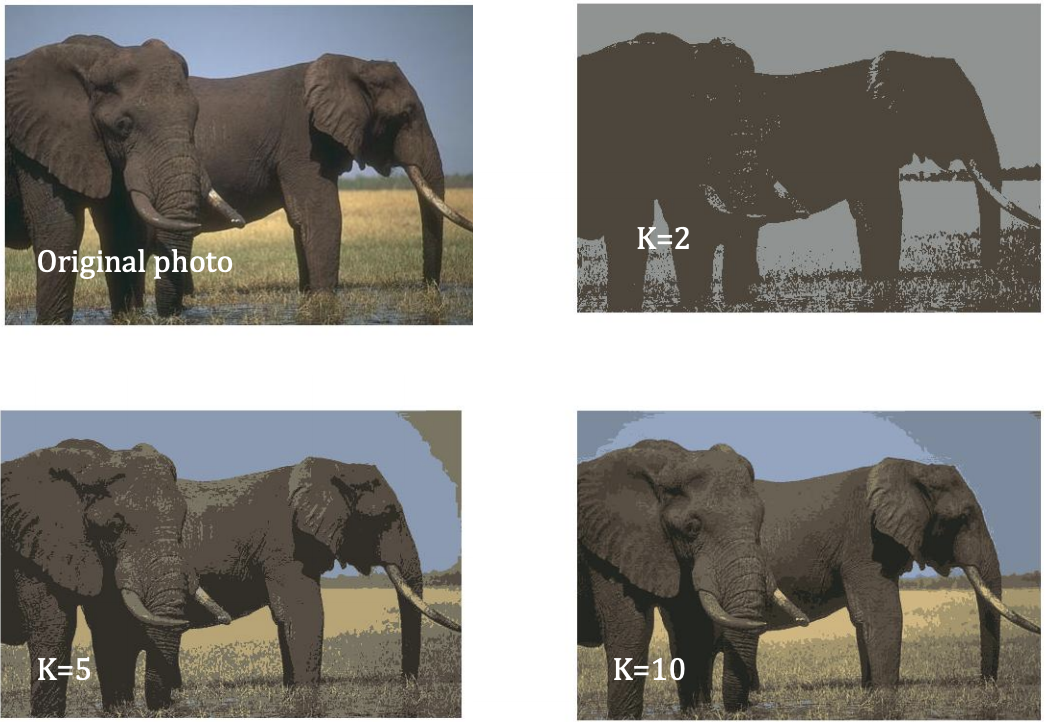

Figure 1. Segmentation of the image into different segments based on K-Means algorithm

## K-Means Implementation

## Step 1: K-Means Algorithm

Write your code in the file "KMeans.m" included in the folder. Your *KMeans*(Image,K,maxIter) function takes in 3 inputs — **1) Image**, to run K-Means segmentation on, **2) K**, denoting the number of segments you wish to classify the pixels of the image image into, **3) maxIter**, specifying the upper bound on the number of iterations before the code terminates. The *KMeans *function should ouput the following — 1) final set of coordinates of the K centroids, 2) final segmented image based on the K centroids. 

% [centroid_coord, segmented_image] = KMeans(Image,K,maxIter);

## Step 2: Testing 

Load elephant.jpg and eiffel.jpg images and run K-Means, with K = 2, K = 5 and K = 10 on both the images. Generate ***two*** figures, for elephant and eiffel images, with each figure having 4 subplots with the original image and segmented images (see Fig. 1).

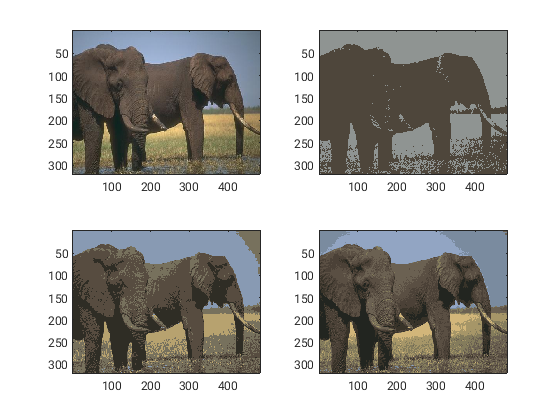

elephant = imread('elephant.jpg');
figure();
subplot(2,2,1);
imagesc(elephant);
subplot(2,2,2);
[c2, x2] = KMeans(elephant, 2, 100);
imagesc(x2);
subplot(2,2,3);
[c5, x5] = KMeans(elephant, 5, 100);
imagesc(x5);
subplot(2,2,4);
[c10, x10] = KMeans(elephant, 10, 100);
imagesc(x10);

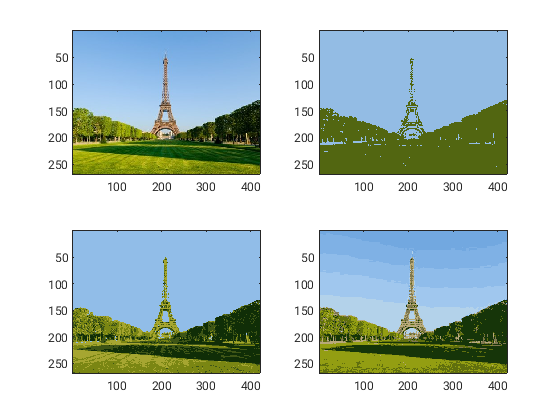

eiffel = imread('eiffel.jpg');
figure();
subplot(2,2,1);
imagesc(eiffel);
subplot(2,2,2);
[c2, x2] = KMeans(eiffel, 2, 100);
imagesc(x2);
subplot(2,2,3);
[c5, x5] = KMeans(eiffel, 5, 100);
imagesc(x5);
subplot(2,2,4);
[c10, x10] = KMeans(eiffel, 10, 100);
imagesc(x10);

## Step 3: Comparison with MATLAB K-Means

Now use the inbuilt MATLAB *kmeans* function and compare the output for the elephant.jpg image **only.** You code should generate*** one ***figure with the original image, segmented image from your K-Means code with K = 5, segmented image from the MATLAB K-Means function with K = 5.

X = reshape(single(elephant), [321*481, 3]);
tic;
[IDX, C] = kmeans(X, 5, 'Maxiter', 100, 'Distance', 'cityblock');
toc;

Elapsed time is 0.302670 seconds.


ref = uint8(reshape(C(IDX, :), [321, 481, 3]));

tic;
[junk, elephant_x5] = KMeans(elephant, 5, 100);
toc;

Elapsed time is 1.666465 seconds.


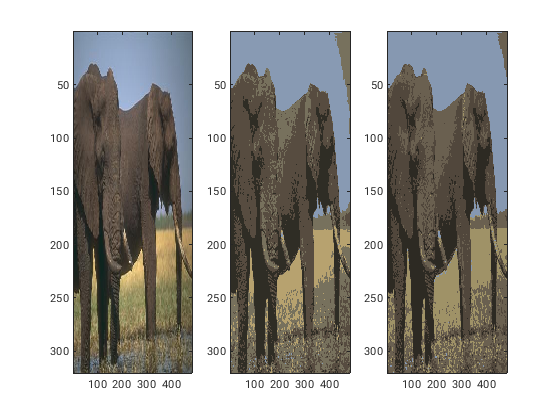


figure();
subplot(1, 3, 1);
imagesc(elephant);
subplot(1, 3, 2);
imagesc(elephant_x5);
subplot(1, 3, 3);
imagesc(ref);

## Step 4: Code Optimization (Optional)

Generate the times it takes to run your K-Means and the MATLAB K-Means function with K = 5 on the elephant image. **Print **the runtimes. Try optimizing ***your ***K-Means code to generate the segmented image within the order of a few seconds, in comparison to the MATLAB K-Means computation times.

disp(['the kmeans.m (see edit kmeans) leverages', ...
      'internal calls the thread pool for parallelization.' ...
      'the underlying algorithm is implemented in external' ...
      'compiled languages (maybe fortran or C++)', ...
      'the chance to outperform such implementation', ...
      'in pure matlab is low', ...
      'that said, we can still try to (1) use parfor for', ...
      'parallelization; (2) merge as many operations into', ...
      'a single matrix operation as possible.', ...
      'My code is already able to finish clustering within', ...
      'two seconds.'
     ]);

the kmeans.m (see edit kmeans) leveragesinternal calls the thread pool for parallelization.the underlying algorithm is implemented in externalcompiled languages (maybe fortran or C++)the chance to outperform such implementationin pure matlab is lowthat said, we can still try to (1) use parfor forparallelization; (2) merge as many operations intoa single matrix operation as possible.My code is already able to finish clustering withintwo seconds.
